# Using Simple Moving Average to analyze SNAP

In this sheet, we'll use Bollinger bands to make buy and sell decisions using the past year of Snapchat Stock (SNAP). The analysis uses past data to make buy and sell decisions resulting in some value today.  We'll use this analysis of past data to hone our algorithm for future use.

This analysis uses Bollinger Bands.  Bollinger bands show when a stock has broken out of resistance to either growth or loss.  If the simple moving 20-day average goes above two times the 20-day standard deviation we buy.  If it goes below it we sell.

## Get SNAP data

We will look at stock data from March 1, 2023 to March 1, 2024. We're only reading one stock, so hist_stock_data() returns a single struct. 

snapStruct = hist_stock_data('01032023','01032024','SNAP');
snapCloses = snapStruct.AdjClose; % Get the closing prics
snapDates = snapStruct.Date; % Get the associated dates

## Calculate the 20-day moving average

shortEMA = calculateEMA(snapCloses, 12);
longEMA = calculateEMA(snapCloses, 26);
MCAD = shortEMA - longEMA;
signalLine = calculateEMA(MCAD, 9);
MCADHistogram = MCAD - signalLine;

### Capture the points where shortEMA crosses above and below longEMA

shortEMA crossing above longEMA is a buying sign.  shortEMA crossing below longEMA is a selling sign.  Capture the buying and selling signs.

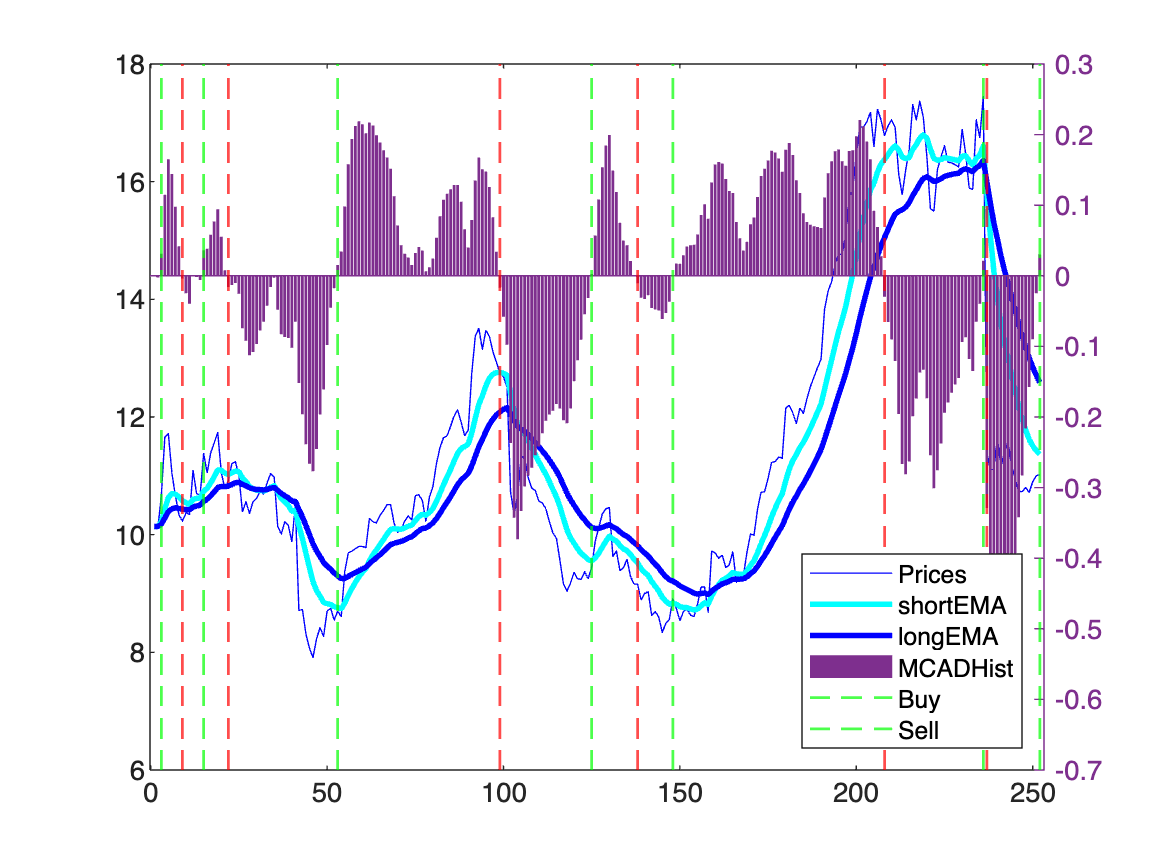

buySignals = false(1,length(shortEMA));
sellSignals = false(1,length(longEMA));

for i = 2:length(MCADHistogram) % Start from the second element to compare with the previous
    if MCADHistogram(i-1) < 0 && MCADHistogram(i) > 0
        % buy signal
        buySignals(i) = true;
    elseif MCADHistogram(i-1) > 0 && MCADHistogram(i) < 0
        % shortEMA crosses below longEMA
        sellSignals(i) = true;
    end
end
buySignals = find(buySignals);
sellSignals = find(sellSignals);
plot(snapCloses,"b-");
hold on;
plot(shortEMA, 'c-',"LineWidth",2);
plot(longEMA, 'b-',"LineWidth",2);
yyaxis right;
bar(MCADHistogram);

for i = 1:numel(buySignals)
    xline(buySignals(i), '--g', 'LineWidth', 1);
end

for i = 1:numel(sellSignals)
    xline(sellSignals(i), '--r', 'LineWidth', 1);
end
legend('Prices', 'shortEMA', 'longEMA','MCADHist','Buy','Sell',"Location","Southeast")

buyDates = snapDates(buySignals);
sellDates = snapDates(sellSignals);
% Timestamp, EmailAddress, Ticker, Type, Shares
transTable = table('Size', [0 5], 'VariableTypes',{'datetime','categorical','categorical','categorical','double'},'VariableNames',{'Timestamp', 'EmailAddress', 'Ticker', 'Type', 'Shares'});
for ii = 1:numel(buyDates)
    transTable = [transTable; {buyDates(ii,1),'rsalemi@natickps.org','SNAP','Buy',10}];
end

for ii = 1:numel(sellDates)
    transTable = [transTable; {sellDates(ii,1),'rsalemi@natickps.org','SNAP','Sell',10}];
end
transTable.Timestamp = datestr(transTable.Timestamp,'mm/dd/yyyy hh:MM:ss');
transTable = sortrows(transTable,"Timestamp");
writetable(transTable,'snapTransactions.csv');

